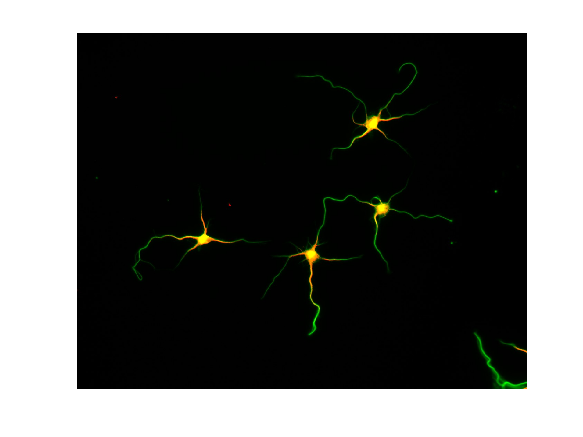

format longG

I = imread('2891.jpg');
I1 = imread('2986.jpg');
I_ = I ;
I0 = zeros(size(I));
imshow(I,[])

[m, n, k] = size(I);

for d = 1: k % according to staining 
    I_(:,:,d) = mean_filter(I(:,:,d),4);    
end

ans =         1034        1304


ans =         1034        1304


ans =         1034        1304


%feature extraction(features can be used for cell detection)
%kse =  Haarlikefeature(I0(:,:,1), winL);
%Maximum level to which to perform the 2-D Haar transform, specified as a positive integer. The default value depends on the length of the input signal, x.
%If both the row and column sizes of x are powers of two, the 2-D Haar transform is obtained down to level log2(min(size(x))).
%If both the row and column sizes of x are even, but at least one is not a power of two, level is equal to floor(log2(min(size(x)/2))).
level = floor(log2(min(size(I_(:,:,1))/2)));
[a,h,v,d] = haart2(I_(:,:,1),level,'integer');

nn = 1;%length(h) choose batch size
ah = size(h{nn},1);
bh = size(h{nn},2);
winL1h = uint32(floor(m/ah));
winL2h = uint32(floor(n/bh));

av = size(v{nn},1);
bv = size(v{nn},2);
winL1v = uint32(floor(m/av));
winL2v = uint32(floor(n/bv));

ad = size(d{nn},1);
bd = size(d{nn},2);
winL1d = uint32(floor(m/ad));
winL2d = uint32(floor(n/bd));
%   [Imaxx, indx] = max(I_);% can be set according to the staining color as [R,G,B]
%    [Imaxy, indy] =
%    max(Imaxx);..................................................................................................-------------------------------------------------------------------------------------------------------------------------------------.......................................................................................................................................................................................................................................................................................................................................................................
%    indy = find(Imaxx == max(Imaxx));
    I11 = I_(:, :, 1);
%    threshold = 0.8*max(max(I11)); % Imaxy*0.05;
    lt =  0.8*(max(max(I11)));%max(max(I_))*0.05;
    
    
    I0(I11> lt) = I11(I11> lt);
    % label;
    Yh = getlb(I11, lt, ah, bh, winL1h, winL2h);
    Yv = getlb(I11, lt, av, bv, winL1v, winL2v);
    Yd = getlb(I11, lt, ad, bd, winL1d, winL2d);

%    Indx = indx(indy);
%    center = [Indx', indy'];
%    [idx, idy] = find(I_ >= threshold);
%    I0(idx, idy, 1)= 1;

% for n1 = 1:length(h)
%      Sh = repmat(0.0000001, [1, n1]);
%      Sh(n1)= features(h{n1});
% end
% for n2 = 1:length(v)
%      Sv = repmat(0.0000001, [1, n2]);
%      Sv(n2)= features(v{n2});
% end
% for n3 = 1:length(d)
%     Sd = repmat(0.0000001, [1, n3]);
%     Sd(n3)= features(d{n3});
% end
%S = [Sh;Sv;Sd];

S= [h{nn}(:)';v{nn}(:)';d{nn}(:)'];
kse = S;
Nn = size(S, 2);
F = kse;
%F = F(F> 0);   
Y = [Yh(1:Nn);Yv(1:Nn);Yd(1:Nn)];

W= repmat(1/3, [3, Nn]);
N = 50;
% sum(mean(F>0==(Y==1),1))
% sum(mean(F>mean(F,1)==(Y==1),1))
% sum(mean(abs(repmat(1,[1,Nn])./(1+exp(-F*Nn)))>0.5==(Y==1),1))
F(abs(repmat(1,[1,Nn])./(1+exp(-F*Nn)))>0.5)= 1;
F(abs(repmat(1,[1,Nn])./(1+exp(-F/Nn)))<0.5)= 0;
%F(F>=0)= 1;
%F(F<0)= 0;
Beta = W;
while N >0 
    change = 0;
    for l = 1:size(F,1)
        w = W(l,:);
        err = w.*abs(F(l,:) - Y(l,:));
        beta = err./(1-err);
        wt = w.*beta;
        wt = wt/sum(wt);
        errt = wt.*abs(F(l,:) - Y(l,:));
        if sum(err>errt)~= 0      
            err(err >errt) = errt(err >errt);
            W(l,err >errt) = w(err >errt);
            Beta(l,err >errt) = beta(err >errt);
            change = l;
        end
    end
    N = N-1;
    if change == 0
        break;
    end
end
row = find(sum(Beta, 2) ~= 0,2);
Beta = Beta(row,:);
alpha = -log(Beta);
fnew = F(row,:); 
Ypred = sum(alpha.*fnew, 1);
Ylb = sum(Beta.*Y(row,:), 1);
YLB = zeros(1, size(Ylb,2));
YLB(Ylb >= 0.5*sum(Beta, 1)) = 1;
YLB(Ylb< 0.5*sum(Beta, 1)) = 0;
YPRED = zeros(1, size(Ypred,2));
YPRED (Ypred >= 0.5*sum(alpha, 1)) = 1;
YPRED (Ypred < 0.5*sum(alpha, 1)) = 0;

acc = sum(sum(YPRED == YLB))/length(Ylb)

acc =           0.95498431665422


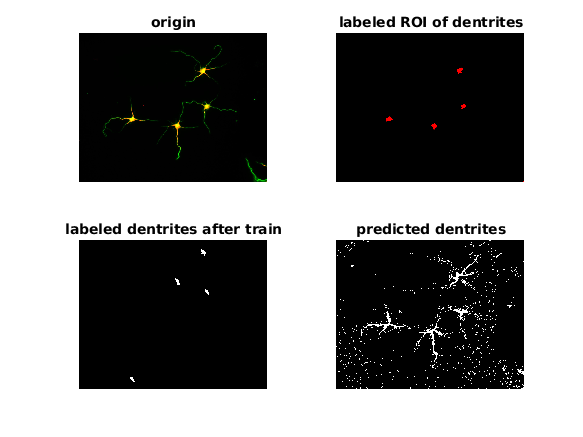

train = YLB;
train(YLB == 1) = 255;
train = reshape(train, 515,650);
YPRED(YPRED == 1) = 255;
YPRED = reshape(YPRED, 515,650);


figure,
subplot(2,2,1)
imshow(imresize(I,0.5),[])
title('origin')
subplot(2,2,2)
imshow(imresize(I0,0.5),[])
title('labeled ROI of dentrites')
subplot(2,2,3)
imshow(train,[])
title('labeled dentrites after train')
subplot(2,2,4)
imshow(YPRED,[])
title('predicted dentrites')



[cx, cy] = find(I11> lt);
figure,
subplot(4,1,1)
scatter(cx,cy);
title('ROI points');  
subplot(4,1,2)
Z = linkage([cx, cy],'average','chebychev');
%Z = linkage([cx, cy],'ward','euclidean');
lastTen = Z(end-9:end,:)

lastTen =                       6056                      6093          15.1259489868371
                      6073                      6096          15.9718119006492
                      6092                      6094           16.884295347555
                      6087                      6099          17.1961673502871
                      6095                      6098          18.4544178029129
                      5662                      6017          106.595238095238
                      6097                      6101          203.804081632653
                      6102                      6104          326.221644433351
                      6100                      6105           431.70471920371
                      6103                      6106          702.997731547449


plot(lastTen(:,3))
title('ward distance v.s clusters')
subplot(4,1,3)
c = cluster(Z, "maxclust",4, 'Depth',4);
crosstab(c)

ans =          909
        1428
         688
          29


cutoff = median([Z(end-3,3) Z(end-2,3) Z(end-1,3)]);
dendrogram(Z,'ColorThreshold',cutoff)

subplot(4,1,4)
c1 = cluster(Z, "maxclust",6, 'Depth',8);
crosstab(c1)

ans =      8
    21
   588
   840
   909
   688


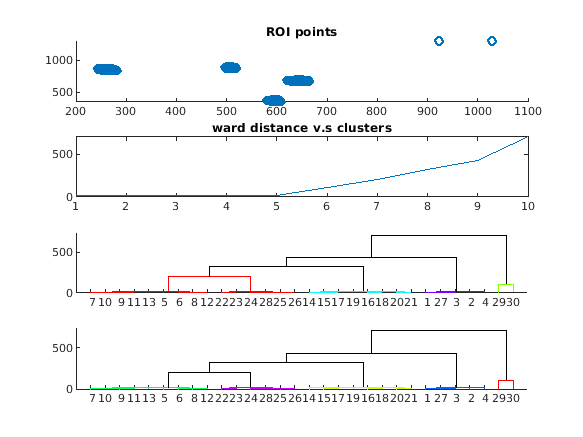

cutoff = median([Z(end-5,3) Z(end-4,3) Z(end-3,3) Z(end-2,3) Z(end-1,3)]);
dendrogram(Z,'ColorThreshold',cutoff)